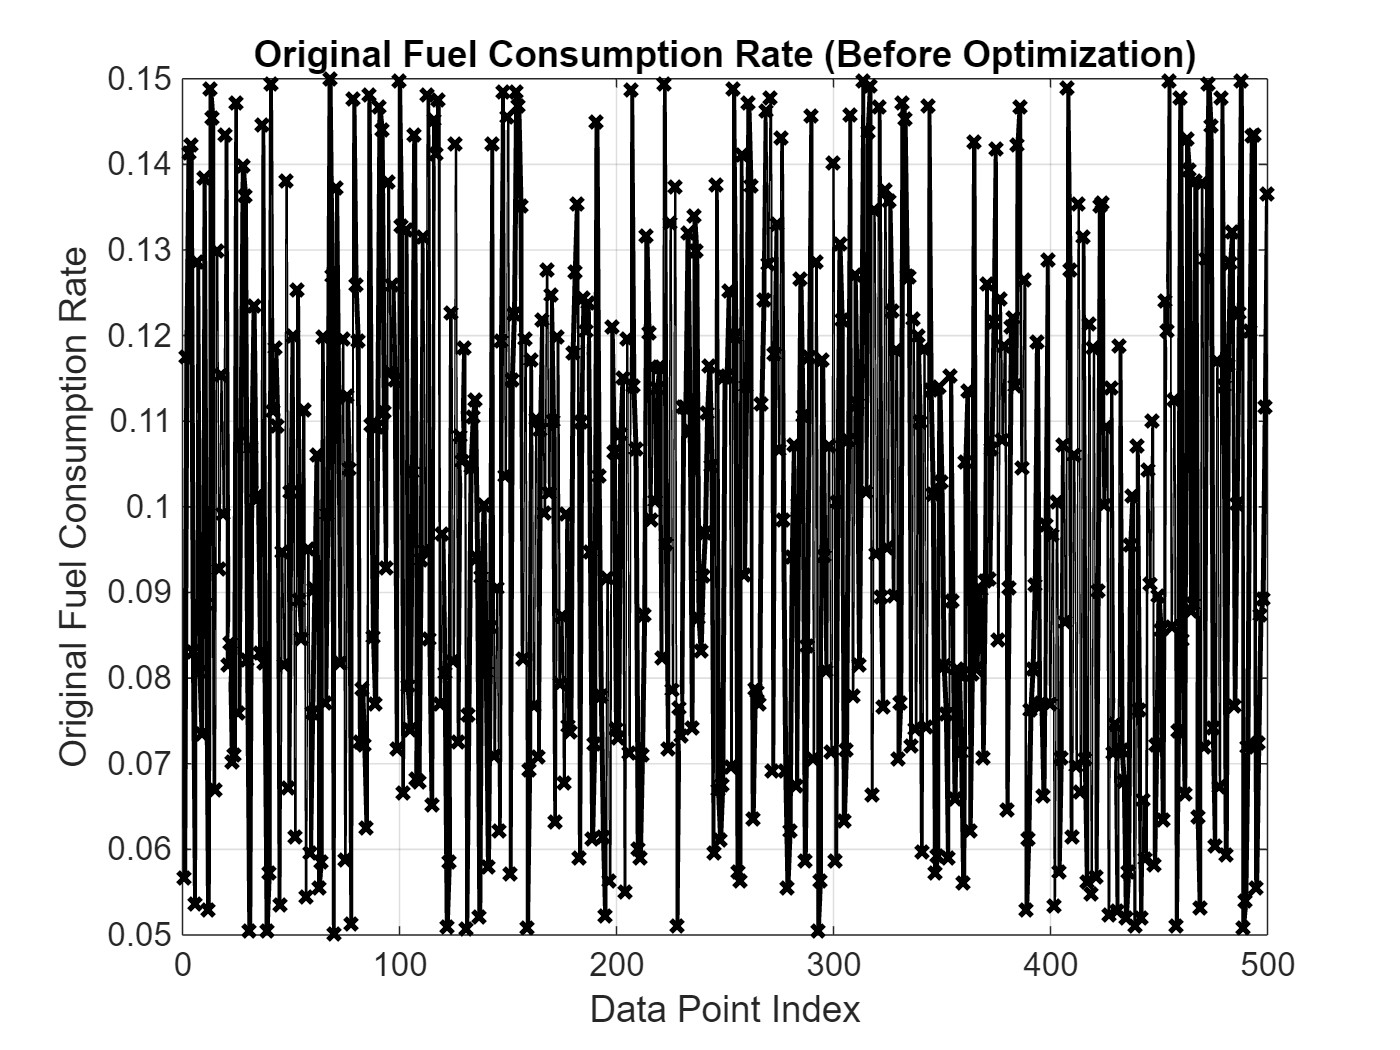

% Spacecraft Trajectory Optimization with SVD and Regression

% Load the dataset
file_path = "C:\Users\Sahaana Shri\Downloads\mars.xlsx";
data = readtable(file_path);

% Extract features (independent variables) and target (fuel consumption rate)
features = data{:, {'x_position', 'y_position', 'z_position', 'x_velocity', 'y_velocity', ...
                    'z_velocity', 'x_acceleration', 'y_acceleration', 'z_acceleration'}};
fuel_consumption_rate = data.Fuel_Consumption_Rate;

% Normalize the features and target for better numerical stability
features_scaled = normalize(features);
fuel_consumption_scaled = normalize(fuel_consumption_rate);

% Perform Singular Value Decomposition (SVD)
[U, S, V] = svd(features_scaled, 'econ');

% Retain the first k principal components for dimensionality reduction
k = 5; % Number of components to keep
reduced_features = U(:, 1:k) * S(1:k, 1:k); % Reduced features (A)

% Optimize the dataset by reconstructing it with reduced dimensions
optimized_trajectory = reduced_features * V(:, 1:k)';

% Extract the optimized fuel consumption rate
optimized_fuel_consumption_rate = optimized_trajectory(:, end);

% Perform manual regression to predict fuel consumption
y = optimized_fuel_consumption_rate; % Target variable (optimized fuel consumption)
A = reduced_features;               % Reduced features matrix

% Calculate regression coefficients (w) using least squares
w = (A' * A) \ (A' * y); % Regression coefficients

% Predict fuel consumption rate using the regression model
y_pred = A * w;


% Plot 1: Original fuel consumption rate
figure;
plot(1:length(fuel_consumption_rate), fuel_consumption_rate, '-x', 'Color', 'k', ...
    'LineWidth', 1.5, 'MarkerSize', 5);
xlabel('Data Point Index');
ylabel('Original Fuel Consumption Rate');
title('Original Fuel Consumption Rate (Before Optimization)');
grid on;

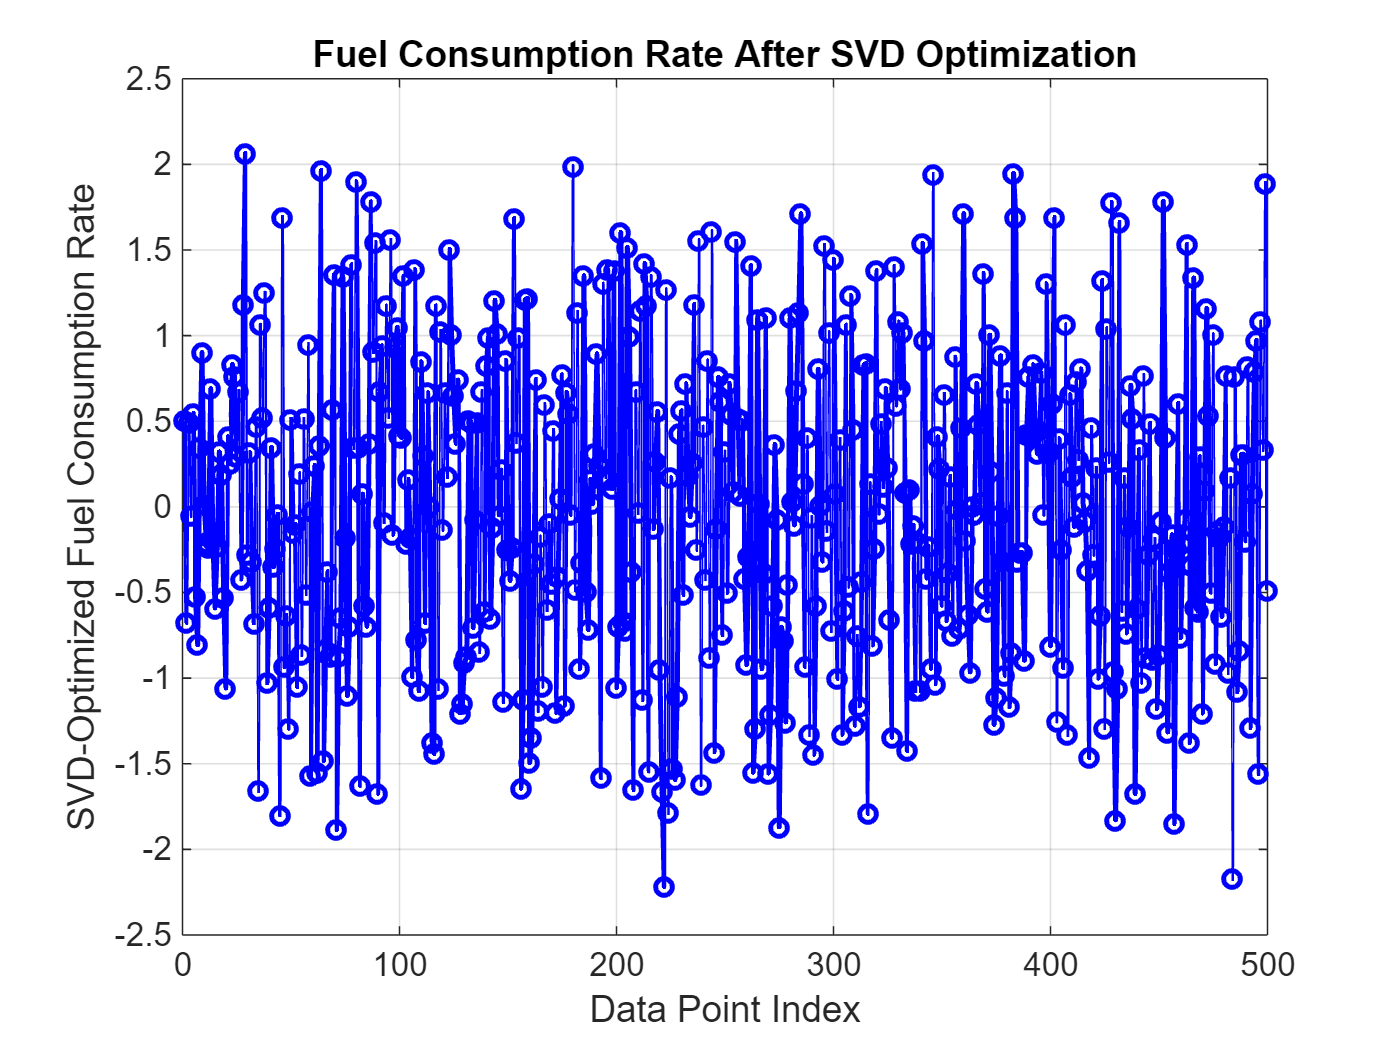


% Plot 2: Optimized fuel consumption rate (SVD)
figure;
plot(1:length(optimized_fuel_consumption_rate), optimized_fuel_consumption_rate, '-o', ...
    'Color', 'b', 'LineWidth', 1.5, 'MarkerSize', 5);
xlabel('Data Point Index');
ylabel('SVD-Optimized Fuel Consumption Rate');
title('Fuel Consumption Rate After SVD Optimization');
grid on;

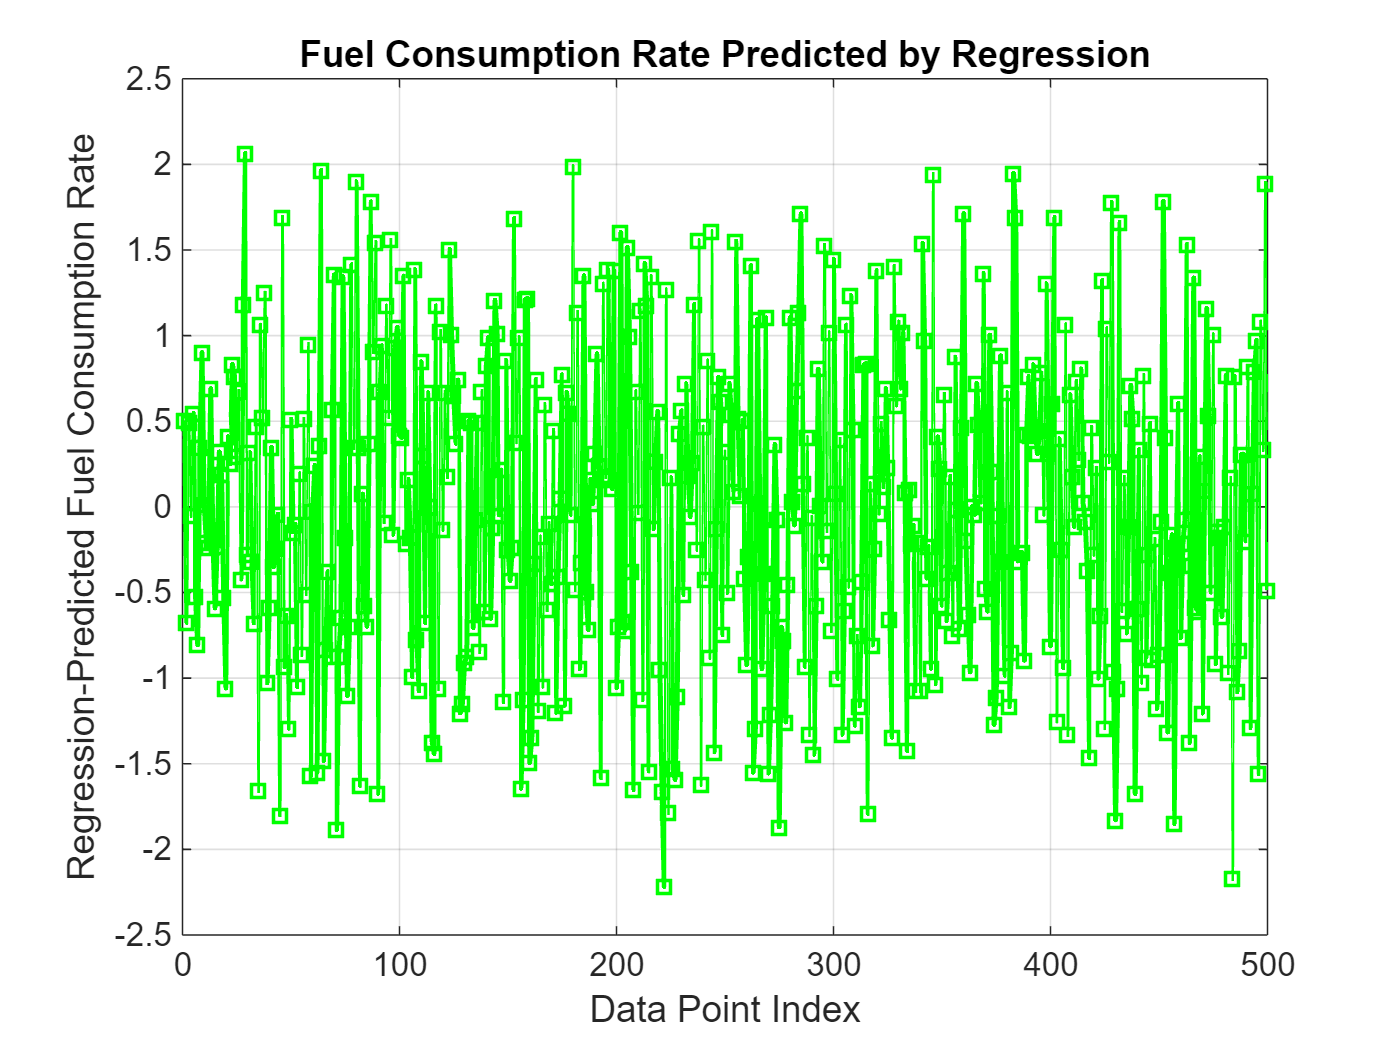


% Plot 3: Regression-predicted fuel consumption rate
figure;
plot(1:length(y_pred), y_pred, '-s', 'Color', 'g', 'LineWidth', 1.5, 'MarkerSize', 5);
xlabel('Data Point Index');
ylabel('Regression-Predicted Fuel Consumption Rate');
title('Fuel Consumption Rate Predicted by Regression');
grid on;

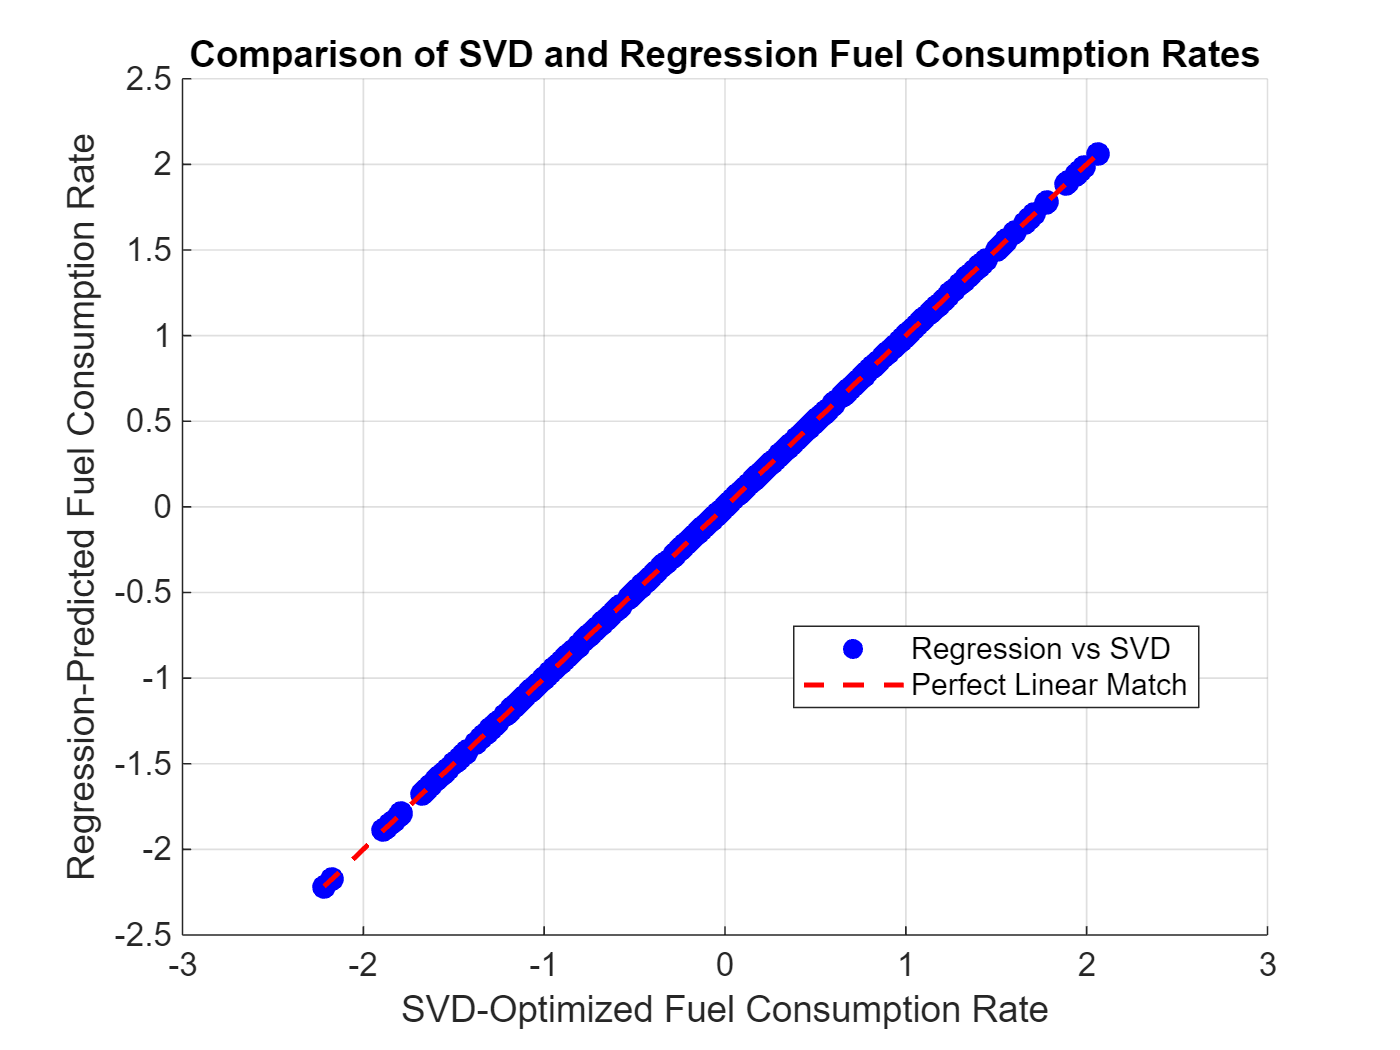


% Plot 4: Comparison of SVD vs Regression fuel consumption rates
figure;
scatter(optimized_fuel_consumption_rate, y_pred, 50, 'b', 'filled'); % Scatter plot
hold on;
plot([min(optimized_fuel_consumption_rate), max(optimized_fuel_consumption_rate)], ...
     [min(optimized_fuel_consumption_rate), max(optimized_fuel_consumption_rate)], 'r--', 'LineWidth', 1.5); % Reference line (y=x)
xlabel('SVD-Optimized Fuel Consumption Rate');
ylabel('Regression-Predicted Fuel Consumption Rate');
title('Comparison of SVD and Regression Fuel Consumption Rates');
legend('Regression vs SVD', 'Perfect Linear Match', 'Location', 'Best');
grid on;
hold off;

[nRows, nCols] = size(optimized_trajectory);
% Save the optimized trajectory to an Excel file
variableNames = strcat("Var", string(1:nCols)); 
optimized_file_path = "C:\Users\Sahaana Shri\Downloads\optimized_spacecraft_trajectory.xlsx";
writetable(optimized_trajectory_table, optimized_file_path);
disp(['Optimized trajectory saved to: ', optimized_file_path]);

    "Optimized trajectory saved to: "    "C:\Users\Sahaana Shri\Downloads\optimized_spacecraft_trajectory.xlsx"




% Save comparison results to an Excel file
results_table = table(optimized_fuel_consumption_rate, y_pred, y - y_pred, ...
    'VariableNames', {'Optimized_Fuel_Consumption', 'Regression_Predicted', 'Prediction_Error'});
results_file_path = 'C:\Users\Sahaana Shri\Downloads\svd_regression_comparison.xlsx';
writetable(results_table, results_file_path);
disp(['Comparison results saved to: ', results_file_path]);

Comparison results saved to: C:\Users\Sahaana Shri\Downloads\svd_regression_comparison.xlsx



% Accuracy Evaluation
% Calculate MAE, RMSE, and R-squared
MAE = mean(abs(y - y_pred)); % Mean Absolute Error
RMSE = sqrt(mean((y - y_pred).^2)); % Root Mean Squared Error

% Display evaluation metrics
disp(['Mean Absolute Error (MAE): ', num2str(MAE)])

Mean Absolute Error (MAE): 3.4054e-16


disp(['Root Mean Squared Error (RMSE): ', num2str(RMSE)])

Root Mean Squared Error (RMSE): 4.2121e-16
